clc
clear all
close all
rng(0)

# MMCC Simulation

## Current topology: M2C

## Parameters

Simulation and control steps

Tf = 1;          % Total simulation time
fs = 6e3;
Ts = 1/fs        % Sampling time

Ts = 1.6667e-04

Ns = ceil(Tf/Ts) % Number of sampling steps

Ns = 6000

Ni = 40;         % Number of integration steps between each ISR (Interrupt Service Routine)
Ti = Ts/Ni	     % Integration step

Ti = 4.1667e-06

Tsim = linspace(0, Tf, Ns);

Ax0 = 4*130/2;
Ay0 = 380*sqrt(2/3)*30/50;
wx0 = 0;
wy0 = 2*pi*50;

[ix_max, iy_max, is_max, vo_max, vB_max, VCdiff, eta] = max_values(Ax0, Ay0, 'M2C')

ix_max = 4.2960

iy_max = 4

is_max = 8.5000

vo_max = 223.0806

vB_max = 446.1612

VCdiff = 0.1000

eta = 1.4416

## Modular Multilevel Cascaded Converter (MMCC)

Specifications

specsMMCC = struct();

specsMMCC.Topology = 'M2C';    % Converter topology M3C/M2C
specsMMCC.Ti       = Ti;       % Integration step
specsMMCC.Rb       = 0.2;      % Branch resistance
specsMMCC.Lb       = 5e-3;     % Branch inductance
specsMMCC.Csm      = 987e-6;   % Submodule capacitance
specsMMCC.Nsm      = 4;        % Submodules per cluster
specsMMCC.Rx       = 1e-3;     % Input filter resistance
specsMMCC.Lx       = 0.1e-3;   % Input filter inductance
specsMMCC.Ry       = 1;        % Output load resistance
specsMMCC.Ly       = 200e-3;   % Output load inductance

Initial values

init_valsMMCC = struct();

init_valsMMCC.is0 = zeros(6, 1);                     % Cluster current
init_valsMMCC.vc0 = (vB_max + vo_max) * ones(6, 1);  % Cluster capacitor voltage

Create object

MMCC = ClassMMCC(specsMMCC, init_valsMMCC);

MMCC =   ClassMMCC with properties:

     Topology: 'M2C'
            A: [5×6 double]
           ax: [2×6 double]
           ay: [3×6 double]
        pinvA: [6×5 double]
            m: 6
            N: [6×2 double]
            n: 2
        pinvN: [2×6 double]
            p: 2
            q: 3
           Ti: 4.1667e-06
           Rb: 0.2000
           Lb: 0.0050
          Csm: 9.8700e-04
          Nsm: 4
            C: 2.4675e-04
           Rx: 1.0000e-03
           Lx: 1.0000e-04
           Ry: 1
           Ly: 0.2000
           Mx: [6×6 double]
           My: [6×6 double]
           As: [6×6 double]
           Bs: [6×6 double]
           Ad: [6×6 double]
           Bd: [6×6 double]
    init_vals: [1×1 struct]
          ixy: [5×1 double]
           is: [6×1 double]
           iB: [6×1 double]
           iz: [6×1 double]
           ie: [2×1 double]
           vc: [6×1 double]
           Ec: [6×1 double]

## External system (IOGrid)

Specifications

specsIOGrid = struct();

specsIOGrid.Ti = Ti;
specsIOGrid.Ax = Ax0;
specsIOGrid.Ay = Ay0;
specsIOGrid.p  = MMCC.p;
specsIOGrid.q  = MMCC.q;

Initial values

init_valsIOGrid = struct();

init_valsIOGrid.gx0 = 0;
init_valsIOGrid.gy0 = 0;
init_valsIOGrid.wx0 = wx0;
init_valsIOGrid.wy0 = wy0;

Create object

IOGrid = ClassIOGrid(specsIOGrid, init_valsIOGrid);

IOGrid =   ClassIOGrid with properties:

     Ti: 4.1667e-06
     Ax: 260
     Ay: 186.1612
      p: 2
      q: 3
     wx: 0
     wy: 314.1593
     gx: 0
     gy: 0
    vxy: [5×1 double]

## Phase Locked Loops (PLL)

[ImperixPLL](https://imperix.com/doc/implementation/synchronous-reference-frame-pll)

Specifications

xi_pll = 1/sqrt(2);
wc_pll = 100*2*pi;

specsPLL = struct();

specsPLL.Ts    = Ts;
specsPLL.kp    = 2*xi_pll*wc_pll;
specsPLL.ki    = wc_pll^2;
specsPLL.u_min = -Inf;
specsPLL.u_max = Inf;

Create objects

if strcmp(MMCC.Topology, 'M3C')
    PLLx = ClassPLL(specsPLL);
end

PLLy =   ClassPLL with properties:

        g: 0
        w: 0
       Ts: 1.6667e-04
       kp: 888.5766
       ki: 3.9478e+05
    u_min: -Inf
    u_max: Inf
       b0: -855.6779
       b1: 921.4753
       a0: -1
       a1: 1
      e_t: 0
    e_t_1: 0
      u_t: 0
    u_t_1: 0

PLLy = ClassPLL(specsPLL);

## TEB PI and Filter design

Plant model

% (Mean cluster capacitor voltage)/(Input current) transfer function
vc_mean_ref = vB_max + vo_max;
if strcmp(MMCC.Topology, 'M3C')
    k_teb = Ax0 / (6 * vc_mean_ref) / MMCC.C;
elseif strcmp(MMCC.Topology, 'M2C')
    k_teb = Ax0 / (3 * vc_mean_ref) / MMCC.C;
end

k_teb = 524.8218

G_teb = k_teb * tf(1, [1, 0])


G_teb =
 
  524.8
  -----
    s
 
Continuous-time transfer function.


Closed loop poles assignment (one first and one second order poles)

% Second order pole
xi_acl    = 1 / sqrt(2); % Damping factor
wn_acl    = 2 * pi * 15; % Natural frequency
% First order pole
alpha_acl = 2 * pi * 15; % Natural frequency

% PI
kp_pi   = wn_acl*(wn_acl+2*xi_acl*alpha_acl)/(k_teb*(2*wn_acl*xi_acl+alpha_acl))

kp_pi = 0.1796

ki_pi   = wn_acl^2*alpha_acl/(k_teb*(2*wn_acl*xi_acl+alpha_acl))

ki_pi = 7.0106

% Filter
wn_filt = 2*wn_acl*xi_acl+alpha_acl

wn_filt = 227.5343

## Low Pass Filter for Mean Energy (LPF)

Specifications

specsLPF = struct();

specsLPF.Ts = Ts;
specsLPF.wn = wn_filt;

Initial values

init_valsLPF = struct();

init_valsLPF.y0 = mean(MMCC.vc);

Create object

LPF = ClassLPF(specsLPF, init_valsLPF);

LPF =   ClassLPF with properties:

        Ts: 1.6667e-04
        wn: 227.5343
        b0: 0.0379
        b1: 0.0379
        a0: -1.9621
        a1: 2.0379
       y_t: 669.2418
     y_t_1: 669.2418
      yf_t: 669.2418
    yf_t_1: 669.2418

## Total Energy Balance Proportional Integral Controller (PI)

Specifications

specsPI = struct();

specsPI.Ts    = Ts;
specsPI.kp    = kp_pi;
specsPI.ki    = ki_pi;
specsPI.u_min = -ix_max;
specsPI.u_max = ix_max;

Create object

PI = ClassPI(specsPI);

PI =   ClassPI with properties:

       Ts: 1.6667e-04
       kp: 0.1796
       ki: 7.0106
    u_min: -4.2960
    u_max: 4.2960
       b0: -0.1790
       b1: 0.1802
       a0: -1
       a1: 1
      e_t: 0
    e_t_1: 0
      u_t: 0
    u_t_1: 0

## Cluster Energy Model Predictive Controller (CEMPC)

Cluster energy and capacitor voltage references

vc_mean_ref = vB_max + vo_max

vc_mean_ref = 669.2418

Ec_mean_ref = MMCC.C/2 * vc_mean_ref^2;

vc_ref = vc_mean_ref * ones(MMCC.m, 1);
Ec_ref = Ec_mean_ref * ones(MMCC.m, 1);

Specifications

specsCEMPC = struct();

specsCEMPC.Ts        = Ts;
specsCEMPC.MMCC      = MMCC;
specsCEMPC.is_max    = is_max;
specsCEMPC.vo_max    = vo_max;
specsCEMPC.lambda_z  = (Ec_mean_ref/is_max)^2 * 0.2e-3;
specsCEMPC.lambda_o  = (Ec_mean_ref/vo_max)^2 * 0.5e-3;
% specsCEMPC.lambda_z  = (Ec_mean_ref/is_max)^2 * 2e-3;
% specsCEMPC.lambda_o  = (Ec_mean_ref/vo_max)^2 * 5e-3;
specsCEMPC.lambda_dz = (Ec_mean_ref/is_max)^2 * 2e-6 * 0;
specsCEMPC.lambda_do = (Ec_mean_ref/vo_max)^2 * 2e-6 * 0;
specsCEMPC.lmax      = 10;
specsCEMPC.Np        = 1;
% specsCEMPC.Np        = 10;

specsCEMPC.lambda_z% = 0.085;

ans = 0.0085

specsCEMPC.lambda_o% = 0.0001; 

ans = 3.0678e-05

Create object

CEMPC = ClassCEMPC(specsCEMPC);

CEMPC =   ClassCEMPC with properties:

             Ts: 1.6667e-04
              m: 6
              n: 2
             NN: [6×2 double]
            one: [6×1 double]
             IM: [6×6 double]
            IM2: [6×6 double]
              K: [6×6 double]
             Np: 1
         is_max: 8.5000
         vo_max: 223.0806
       lambda_z: 0.0085
       lambda_o: 3.0678e-05
      lambda_dz: 0
      lambda_do: 0
           lmax: 10
      options_i: [1×1 mpcActiveSetOptions]
      options_v: [1×1 mpcActiveSetOptions]
         ie_ref: [2×1 double]
         iz_ref: [6×1 double]
         vo_ref: 0
    ie_ref_prev: [2×1 double]
    iz_ref_prev: [6×1 double]
    vo_ref_prev: 0
            iAi: [12×1 logical]
            iAv: [2×1 logical]
     exitflag_i: -3
     exitflag_v: -3
       exitflag: -3
            Tex: 0

## Reference Frame Transform (RFT)

RFT = reference_frame_transforms();

ans = function_handle with value:
    @(g)(2/3)*[cos(g),cos(g-2*pi/3),cos(g+2*pi/3);-sin(g),-sin(g-2*pi/3),-sin(g+2*pi/3)]

ans = function_handle with value:
    @(g)[cos(g),-sin(g);cos(g-2*pi/3),-sin(g-2*pi/3);cos(g+2*pi/3),-sin(g+2*pi/3)]

ans =     0.6667   -0.3333   -0.3333
         0    0.5774   -0.5774


ans =     1.0000         0
   -0.5000    0.8660
   -0.5000   -0.8660


pi/2 rotation matrix

rot = [0 -1
       1  0]

rot =      0    -1
     1     0


## Basic Variables Predictor (Predictor)

Predict external voltages and currents for the Cluster Energy MPC

Specifications

specsPredictor = struct();

specsPredictor.MMCC  = MMCC;
specsPredictor.CEMPC = specsCEMPC;
specsPredictor.RFT   = RFT;

Create object

Predictor = BasicVariablesPredictor(specsPredictor);

Predictor =   BasicVariablesPredictor with properties:

     Np: 1
     Ts: 1.6667e-04
    RFT: [1×1 struct]
      A: [5×6 double]
      p: 2
      q: 3

## Cluster Current Model Predictive Controller (CCMPC)

Specifications

% Model for control
specsMMCC_CC = specsMMCC;
specsMMCC_CC.Ti = Ts;
MMCC_CC = ClassMMCC(specsMMCC_CC, init_valsMMCC);

specsCCMPC = struct();

specsCCMPC.Ts       = Ts;
specsCCMPC.MMCC     = MMCC_CC;
specsCCMPC.is_max   = is_max;
specsCCMPC.ix_max   = ix_max;
specsCCMPC.iy_max   = iy_max;
specsCCMPC.zB_ratio = 0.5;
specsCCMPC.lambda   = (is_max / vc_mean_ref)^2 * 0.0001;
specsCCMPC.lambda_d = (is_max / vc_mean_ref)^2 * 0.01*0;

specsCCMPC.lambda

ans = 1.6131e-08

Create object

CCMPC = ClassCCMPC(specsCCMPC);

CCMPC =   ClassCCMPC with properties:

          Ts: []
           m: 6
           p: 2
           q: 3
           A: [5×6 double]
          Ad: [6×6 double]
          Bd: [6×6 double]
          As: [6×6 double]
          Bs: [6×6 double]
      is_max: 8.5000
      ix_max: 4.2960
      iy_max: 4
     ixy_max: [5×1 double]
    zB_ratio: 0.5000
      lambda: 1.6131e-08
    lambda_d: 0
     options: [1×1 mpcActiveSetOptions]
          vs: [6×1 double]
          iA: [34×1 logical]
    exitflag: -3
         Tex: 0

## Cluster voltage steady state reference generator

Specifications

specsRefGen = struct();

specsRefGen.MMCC = MMCC_CC;
specsRefGen.RFT  = RFT;
specsRefGen.rot  = rot;

Create object

vsRefGen = vsRefGenerator(specsRefGen);

vsRefGen =   vsRefGenerator with properties:

    Topology: 'M2C'
       pinvA: [6×5 double]
          As: [6×6 double]
       invBs: [6×6 double]
         RFT: [1×1 struct]
         rot: [2×2 double]

## Buffer

Specifications

specsBuffer = struct();

specsBuffer.Ts   = Ts;
specsBuffer.Ns   = Ns;
specsBuffer.m    = MMCC.m;
specsBuffer.n    = MMCC.n;
specsBuffer.A    = MMCC.A;
specsBuffer.p    = MMCC.p;
specsBuffer.q    = MMCC.q;
specsBuffer.Tsim = Tsim;

Create object

buffer = ClassBuffer(specsBuffer);

buffer =   ClassBuffer with properties:

                 Ts: 1.6667e-04
                 Ns: 6000
                  m: 6
                  n: 2
                  A: [5×6 double]
                  p: 2
                  q: 3
               Tsim: [0 1.6669e-04 3.3339e-04 5.0008e-04 6.6678e-04 8.3347e-04 0.0010 0.0012 0.0013 0.0015 0.0017 0.0018 0.0020 0.0022 0.0023 0.0025 0.0027 0.0028 0.0030 0.0032 0.0033 0.0035 0.0037 0.0038 0.0040 0.0042 0.0043 0.0045 … ] (1×6000 double)
                 is: [6×6000 double]
                ixy: [5×6000 double]
                 iB: [6×6000 double]
                 iz: [6×6000 double]
                 ie: [2×6000 double]
                 vs: [6×6000 double]
                vxy: [5×6000 double]
                 vB: [6×6000 double]
                 vo: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0

## Neural Network

Emean = MMCC.C/2 * vc_mean_ref^2;                    % mean(Ec)
Ediff = Emean * ((1+VCdiff)^2 - 1) *ones(MMCC.m, 1); % Ec-mean(Ec)
IY    = iy_max                     *ones(2, 1);      % iya, iyb
VY    = sqrt(3) * Ay0              *ones(2, 1);      % vyac, vybc
PY    = VY .* IY;                                    % py1, py2

if strcmp(MMCC.Topology, 'M3C')
    IX = ix_max        *ones(2, 1); % ixa, ixb
    VX = sqrt(3) * Ax0 *ones(2, 1); % vxac, vxbc
    PX = VX .* IX;                  % px1, px2

    Xmax = [Emean; Ediff; IY; VY; PY; IX; VX; PX]
elseif strcmp(MMCC.Topology, 'M2C')
    IX = ix_max;                    % ix

    Xmax = [Emean; Ediff; IY; VY; PY; IX]
end

Xmax = 1.0e+03 *

    0.0553
    0.0116
    0.0116
    0.0116
    0.0116
    0.0116
    0.0116
    0.0040
    0.0040
    0.3224
    0.3224
    1.2898
    1.2898
    0.0043



IE = is_max *ones(MMCC.n, 1); % LICCs
VO = vo_max;                  % CMV

Ymax = [IE; VO]

Ymax =     8.5000
    8.5000
  223.0806



% net = load('ImitationLearning\ActualArchitecture\Results_v2.mat').net;

Weight averaging

history = load('ImitationLearning\ActualArchitecture\Results_v2.mat').history;
[~, sorted_idxs] = sort([history.val_loss], 'ascend');
sorted_history = history(sorted_idxs)

sorted_history = 1×6 struct array with fields:
    net
    train_loss
    val_loss

% net = sorted_history(1).net;

M = min(3, numel(sorted_history));
nets = cell(1, M);
for k = 1:M
    nets{k} = sorted_history(k).net;
end
net_avg = nets{1};
tbl     = net_avg.Learnables;
nParams = size(tbl, 1);
for i = 1:nParams
    vals = cellfun(@(n) n.Learnables.Value{i}, nets, 'UniformOutput', false);
    nd = ndims(vals{1});
    stacked = cat(nd+1, vals{:});
    avgVal  = mean(stacked, nd+1);
    net_avg.Learnables.Value{i} = avgVal;
end
net = net_avg;

function Y = NNcontrol(net, X, Xmax, Ymax, VCdiff)
    x = dlarray(X ./ Xmax, 'CB');
    x(1) = (x(1) - 1) / VCdiff;
    y = double(extractdata(net.predict(x)));
    Y = y .* Ymax;
end

## Projector

Specifications

specsProjector = struct();

specsProjector.Ac      = [MMCC.N; -MMCC.N];
specsProjector.MaxIter = 100;
specsProjector.lambda  = 1;
specsProjector.Tol     = 1e-3;
specsProjector.Nx      = MMCC.n;
specsProjector.Method  = 'cimmino-greedy';
Projector = ClassProjector(specsProjector);

# Simulation

Reset

% buffer_name = 'validation';
% load(strcat('ImitationLearning\TrainingData\Data\init_', buffer_name, '.mat'), 'buffer_init')
% buffer_init
% 
% idx = 5;
% init_valsM3C.is0    = buffer_init.VC0(:, idx);
% init_valsM3C.vc0    = buffer_init.IS0(:, idx);
% init_valsIOGrid.gx0 = buffer_init.GX0(:, idx);
% init_valsIOGrid.gy0 = buffer_init.GY0(:, idx);

buffer = buffer.reset();
IOGrid = IOGrid.reset(init_valsIOGrid);
MMCC   = MMCC.reset(init_valsMMCC);

if strcmp(MMCC.Topology, 'M3C')
    PLLx   = PLLx.reset();
end
PLLy   = PLLy.reset();
LPF    = LPF.reset(init_valsLPF);
PI     = PI.reset();
CEMPC  = CEMPC.reset();
CCMPC  = CCMPC.reset();
iyd_ref_filt = 0;

Maneouver

wy_vec = zeros(Ns, 1);

mask = Tsim < 0.1;
wy_vec(mask) = wy0;

mask = and(0.1 < Tsim, Tsim < 0.9);
wy_vec(mask) = linspace(wy0, -wy0, sum(mask));

mask = 0.9 < Tsim;
wy_vec(mask) = -wy0;

Run

% Initialize progress bar
h = waitbar(0, 'Simulating...');

for ts = 1:Ns

%% Measure
% External voltages
vxy = IOGrid.vxy;
vB  = MMCC.A' * vxy;
% Cluster currents
is  = MMCC.is;
ixy = MMCC.A * is;
iB  = MMCC.pinvA * ixy;
iz  = is - iB;
ie  = MMCC.pinvN * iz;

%% Input PLL
if strcmp(MMCC.Topology, 'M3C')
    vxdq = RFT.abc2dq(PLLx.g) * vxy(1:3);
    ixdq = RFT.abc2dq(PLLx.g) * ixy(1:3);
    PLLx = PLLx.estimate(vxdq/norm(vxdq), wx0);
elseif strcmp(MMCC.Topology, 'M2C')
    vxdq = vxy(1:2);
    ixdq = ixy(1:2);
end

%% Output PLL
vydq = RFT.abc2dq(PLLy.g) * vxy(MMCC.p+1:end);
iydq = RFT.abc2dq(PLLy.g) * ixy(MMCC.p+1:end);
PLLy = PLLy.estimate(vydq/norm(vydq), wy0);

%% Measure
% Cluster capacitor voltages and energies
Ec = MMCC.Ec;
vc = MMCC.vc;

Ec_mean = mean(Ec);
vc_mean = mean(vc);

%% Low pass filter for mean cluster voltage
LPF          = LPF.filter(vc_mean);
vc_mean_filt = LPF.yf_t;
Ec_mean_filt = MMCC.C / 2 * vc_mean_filt^2;

%% Calculate input currents references (TEB PI)
PI = PI.control(vc_mean_ref, vc_mean_filt);
if strcmp(MMCC.Topology, 'M3C')
    % dq
    ixd_ref  = PI.u_t;
    ixq_ref  = 0;
    ixdq_ref = [ixd_ref; ixq_ref];
    % abc
    ix_ref   = RFT.dq2abc(PLLx.g) * ixdq_ref;
elseif strcmp(MMCC.Topology, 'M2C')
    ixdq_ref = [PI.u_t; -PI.u_t];
    ix_ref   = ixdq_ref;
end

%% Calculate output currents references (Converter application)
% dq
iyd_ref = -iy_max*0.9;
tau = 0.02;
iyd_ref_filt = (Ts * iyd_ref + tau * iyd_ref_filt) / (Ts + tau);
iyd_ref = iyd_ref_filt;
iyq_ref = 0;
iydq_ref = [iyd_ref; iyq_ref];
% abc
iy_ref = RFT.dq2abc(PLLy.g) * iydq_ref;

%% Concatenate external currents references
ixy_ref = [ix_ref; iy_ref];

%% Basic currents references
iB_ref = MMCC.pinvA * ixy_ref;

%% Predict external voltages/currents
if strcmp(MMCC.Topology, 'M3C')
    vB_pred = Predictor.predict(vxy, PLLx.w, PLLy.w);
    iB_pred = Predictor.predict(ixy, PLLx.w, PLLy.w);
elseif strcmp(MMCC.Topology, 'M2C')
    vB_pred = Predictor.predict(vxy, 0, PLLy.w);
    iB_pred = Predictor.predict(ixy, 0, PLLy.w);
end

%% Cluster energy NNC
iya_iyb   = ixy(MMCC.p+1:end-1);
vyac_vybc = vxy(MMCC.p+1:end-1)-vxy(end);
py1_py2   = iya_iyb .* vyac_vybc;
X = [Ec_mean; Ec-Ec_mean; iya_iyb; vyac_vybc; py1_py2];
if strcmp(MMCC.Topology, 'M3C')
    ixa_ixb   = ixy(1:MMCC.p-1);
    vxac_vxbc = vxy(1:MMCC.p-1)-vxy(MMCC.p);
    px1_px2   = vxac_vxbc .* ixa_ixb;
    X = [X; ixa_ixb; vxac_vxbc; px1_px2];
elseif strcmp(MMCC.Topology, 'M2C')
    ix = ixy(1);
    X = [X; ix];
end
tic
Y = NNcontrol(net, X, Xmax, Ymax, VCdiff);
ie_ref = Y(1:MMCC.n);
vo_ref = Y(end);

NN_Tex = toc;

% Projection
bc = is_max + [-iB; iB];
[ie_ref, time] = Projector.project(ie_ref, bc);
iz_ref = MMCC.N * ie_ref;

% NN_Tex = NN_Tex + time;

%% Cluster current MPC
is_ref = iz_ref + iB_ref;
if strcmp(MMCC.Topology, 'M3C')
    vs_ref = vsRefGen.get_vs_ref(ix_ref, iy_ref, iB_ref, vB, PLLx.w, PLLy.w);
elseif strcmp(MMCC.Topology, 'M2C')
    vs_ref = vsRefGen.get_vs_ref(ix_ref, iy_ref, iB_ref, vB, 0, PLLy.w);
end
CCMPC  = CCMPC.control(is_ref, vc, is, vB, vo_ref, vs_ref);
vs     = CCMPC.vs;

%% Store variables
buffer.is(:, ts)           = is;
buffer.ixy(:, ts)          = ixy;
buffer.iB(:, ts)           = iB;
buffer.iz(:, ts)           = iz;
buffer.ie(:, ts)           = ie;
buffer.vs(:, ts)           = vs;
buffer.vxy(:, ts)          = vxy;
buffer.vB(:, ts)           = vB;
buffer.vo(:, ts)           = vo_ref;
buffer.Ec(:, ts)           = Ec;
buffer.vc(:, ts)           = vc;
buffer.Ec_mean(ts)         = Ec_mean;
buffer.Ec_mean_filt(ts)    = Ec_mean_filt;
buffer.vc_mean(ts)         = vc_mean;
buffer.vc_mean_filt(ts)    = vc_mean_filt;

buffer.u_TEB(ts)           = PI.u_t;

buffer.gx(ts)              = IOGrid.gx;
buffer.wx(ts)              = IOGrid.wx;
buffer.gy(ts)              = IOGrid.gy;
buffer.wy(ts)              = IOGrid.wy;

if strcmp(MMCC.Topology, 'M3C')
    buffer.gx_pll(ts)          = PLLx.g;
    buffer.wx_pll(ts)          = PLLx.w;
    buffer.ex_pll(ts)          = PLLx.e_t;
    buffer.ux_pll(ts)          = PLLx.u_t;
end
buffer.gy_pll(ts)          = PLLy.g;
buffer.wy_pll(ts)          = PLLy.w;
buffer.ey_pll(ts)          = PLLy.e_t;
buffer.uy_pll(ts)          = PLLy.u_t;

buffer.is_ref(:, ts)       = is_ref;
buffer.ixy_ref(:, ts)      = ixy_ref;
buffer.iB_ref(:, ts)       = iB_ref;
buffer.iz_ref(:, ts)       = iz_ref;
buffer.ie_ref(:, ts)       = ie_ref;

buffer.exitflag_CEMPCi(ts) = CEMPC.exitflag_i;
buffer.exitflag_CEMPCv(ts) = CEMPC.exitflag_v;
buffer.exitflag_CCMPC(ts)  = CCMPC.exitflag;

buffer.iA_CEMPCi(ts)       = sum(CEMPC.iAi);
buffer.iA_CEMPCv(ts)       = sum(CEMPC.iAv);
buffer.iA_CCMPC(ts)        = sum(CCMPC.iA);

buffer.ixdq(:, ts)         = ixdq;
buffer.iydq(:, ts)         = iydq;
buffer.ixdq_ref(:, ts)     = ixdq_ref;
buffer.iydq_ref(:, ts)     = iydq_ref;

buffer.vxdq(:, ts)         = vxdq;
buffer.vydq(:, ts)         = vydq;

buffer.Tex_CEMPC(ts)       = NN_Tex;
buffer.Tex_CCMPC(ts)       = CCMPC.Tex;

buffer.vs_ref(:, ts)       = vs_ref;

%% Integrate external system and converter
for ti = 1:Ni
    % Update model
    MMCC = MMCC.step(CCMPC.vs, IOGrid.vxy, vo_ref);

    % Update external system
    IOGrid.wy = wy_vec(ts);
    IOGrid    = IOGrid.step();
end

% Update progress bar
waitbar(ts/Ns, h, sprintf('Simulating: %d%%', round((ts/Ns)*100)));

end

% Close progress bar
close(h)

# Plot

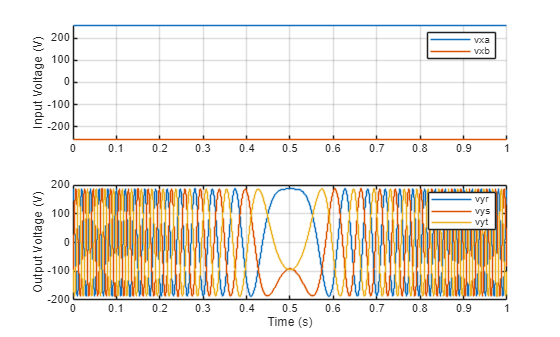

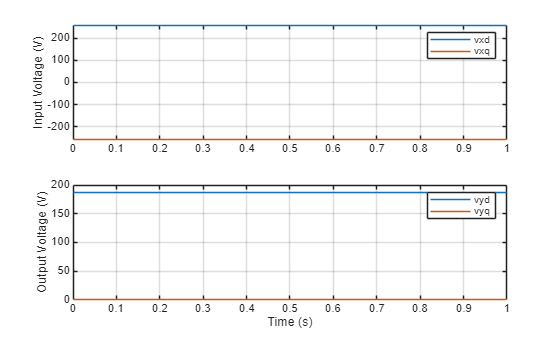

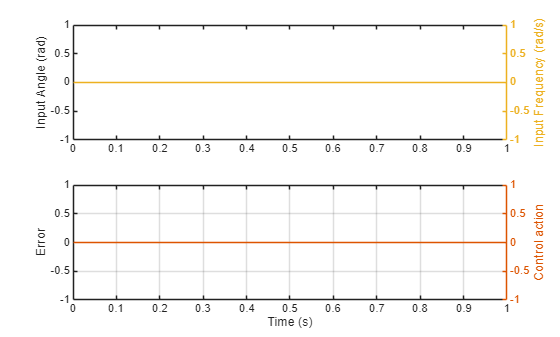

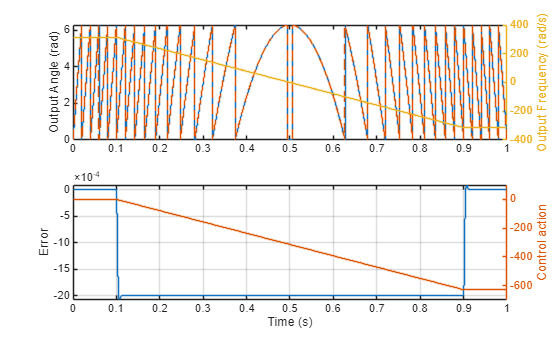

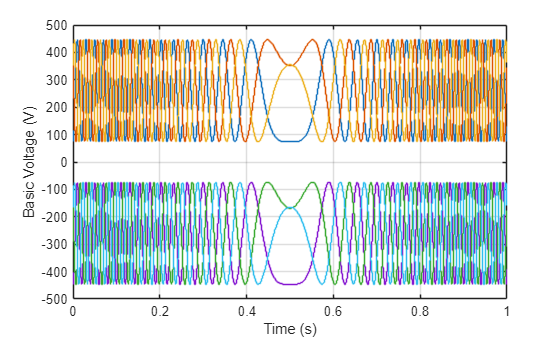

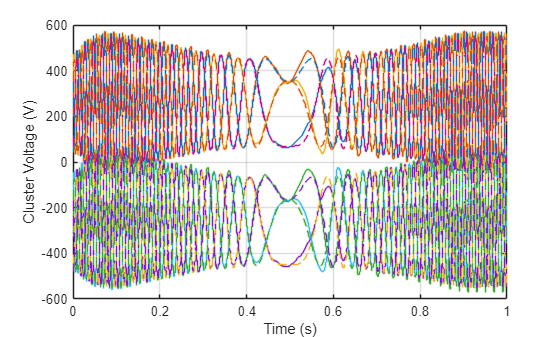

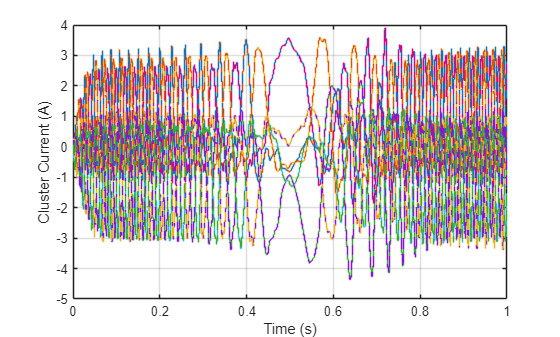

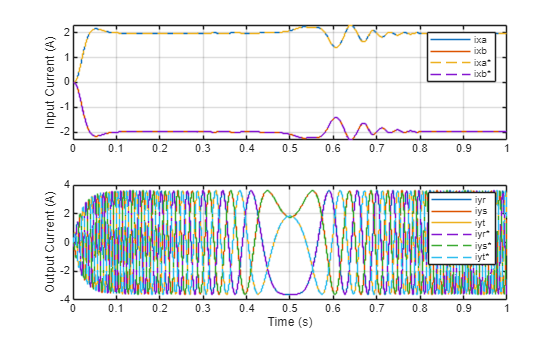

run('Plot.mlx')